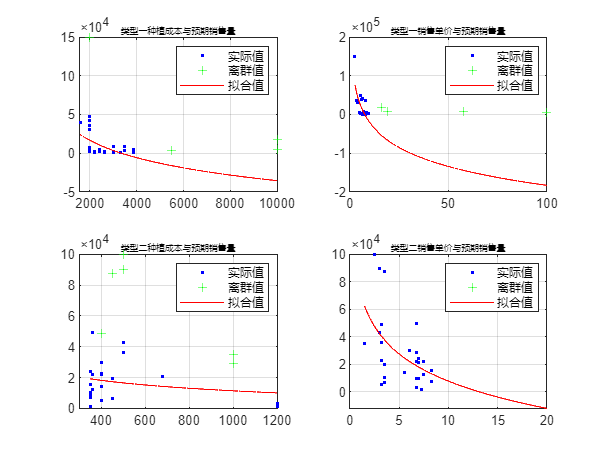

clear,clc

% 装载聚类分析后的两种类别数据
load Type_1.mat
load Type_2.mat

% 提取两类自变量
x11=Type_1(:,1);
x12=Type_1(:,2);
y1=Type_1(:,3);

x21=Type_2(:,1);
x22=Type_2(:,2);
y2=Type_2(:,3);

% 拟合: '类型一种植成本与销售量'。
[xData, yData] = prepareCurveData( x11, y1 );

% 设置 fittype 和选项。
ft = fittype( 'log' );
excludedPoints = excludedata( xData, yData, 'Indices', [18 32 33 34] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts );

% 绘制数据拟合图。
subplot(2,2,1)
%figure( 'Name', '类型一种植成本与销售量' );
plot( fitresult, xData, yData, excludedPoints );
legend('实际值', '离群值', '拟合值', 'Location', 'NorthEast', 'Interpreter', 'none' );
% 为坐标区加标签
xlabel( '', 'Interpreter', 'none' );
ylabel( '', 'Interpreter', 'none' );
xlim([1550,10000])
title('类型一种植成本与预期销售量','FontSize',6)
grid on

% 拟合: '类型一销售单价与销售量'。
[xData, yData] = prepareCurveData( x12, y1 );

% 设置 fittype 和选项。
ft = fittype( 'log' );
excludedPoints = excludedata( xData, yData, 'Indices', [19 20 33 34] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts );

% 绘制数据拟合图
subplot(2,2,2)
%figure( 'Name', '类型一销售单价与销售量' );
 plot( fitresult, xData, yData, excludedPoints );
legend('实际值', '离群值', '拟合值', 'Location', 'NorthEast', 'Interpreter', 'none' );
% 为坐标区加标签
xlabel( '', 'Interpreter', 'none' );
ylabel( '', 'Interpreter', 'none' );
title('类型一销售单价与预期销售量','FontSize',6)
grid on

% 拟合: '类型二种植成本与销售量'。
[xData, yData] = prepareCurveData( x21, y2 );

% 设置 fittype 和选项。
ft = fittype( 'log' );
excludedPoints = excludedata( xData, yData, 'Indices', [1 4 11 22 24 27] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts );

% 绘制数据拟合图。
subplot(2,2,3)
%figure( 'Name', '类型二种植成本与销售量' );
plot( fitresult, xData, yData, excludedPoints );
legend('实际值', '离群值', '拟合值', 'Location', 'NorthEast', 'Interpreter', 'none');
% 为坐标区加标签
xlabel( '', 'Interpreter', 'none' );
ylabel( '', 'Interpreter', 'none' );
xlim([300,1200])
title('类型二种植成本与预期销售量','FontSize',6)
grid on

% 拟合: '类型二销售单价与销售量'。
[xData, yData] = prepareCurveData( x22, y2 );

% 设置 fittype 和选项。
ft = fittype( 'log' );
excludedPoints = excludedata( xData, yData, 'Indices', 21 );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts );

% 绘制数据拟合图。
subplot(2,2,4)
%figure( 'Name', '类型二销售单价与销售量' );
plot( fitresult, xData, yData, excludedPoints );
legend('实际值', '离群值', '拟合值', 'Location', 'NorthEast', 'Interpreter', 'none' );
% 为坐标区加标签
xlabel( '', 'Interpreter', 'none' );
ylabel( '', 'Interpreter', 'none' );
title('类型二销售单价与预期销售量','FontSize',6)
xlim([0,20])
grid on